### **ELE713 - PROJECT                                                                            ***Özgür Gülsuna & İsmail Macit*

First lets acquire the state space representation of the boost converter with output capacitor esr.

# **Boost Converter VMC Design**

- Circuit Topology : Forward Converter, Continous mode

- 
$$V_d =24\;V$$


- 
$$V_o =4\;V$$


- 
$$r_c =10\;m\Omega$$


- 
$$C_f =2000\;\mu F$$


- $r_L =10\;m\Omega$ (ignored)

- 
$$R_L =200\;m\Omega$$


- 
$$L_f =5\;\mu H$$


- 
$$f_s =200\;\textrm{kHz}$$


- 
$$\frac{\textrm{N1}}{\textrm{N2}}=3$$


- 
$$T_m \left(s\right)=0\ldotp 34\;\left(-9\ldotp 37\;\textrm{dB}\right)$$


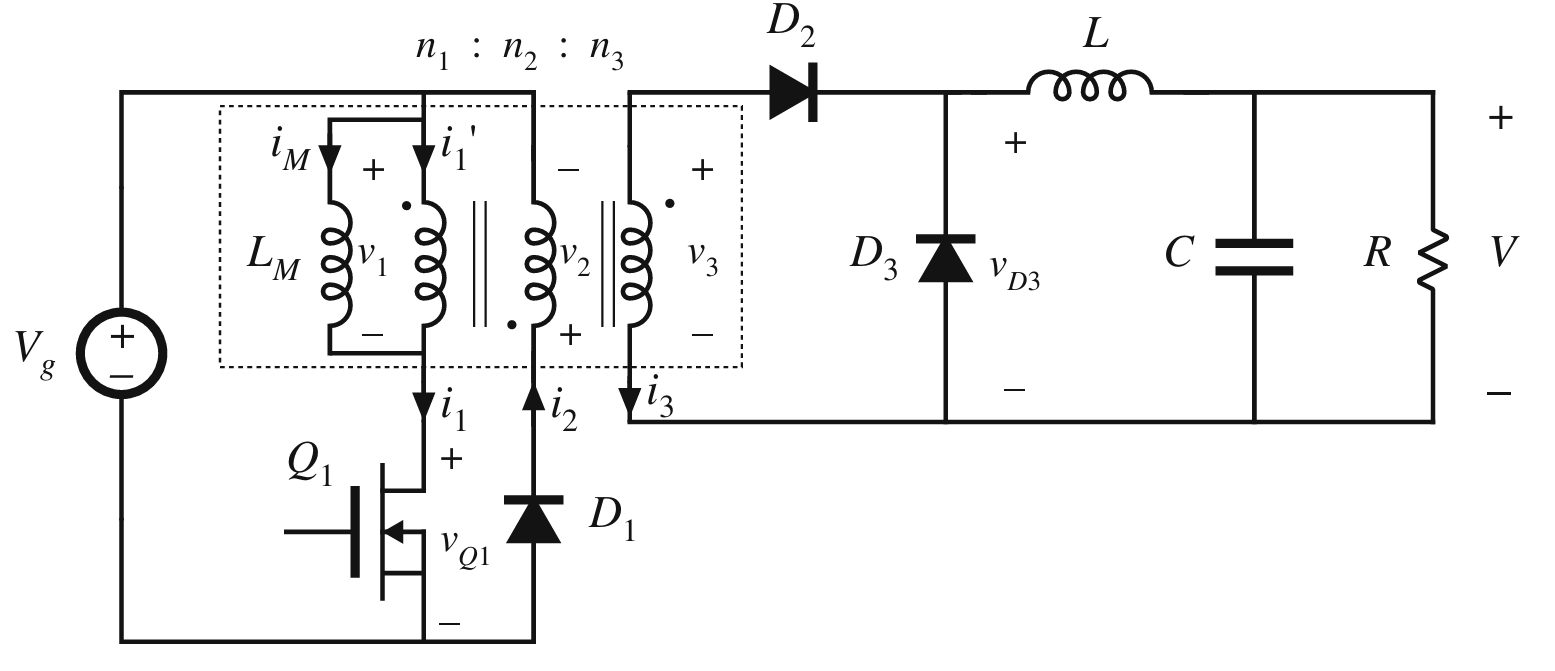

## **Design Steps**

### **Forward Mode Transfer Function**

Forward mode or also known as buck mode one can use voltage mode control strategy.

clc
clear

Vd = 24;          % Input Voltage
Vo = 4;           % Desired Output Voltage
Cf = 2000e-6;     % Output Capacitance
Rc = 0.01;        % Capacitor ESR
Rl = 0;           % Inductor ESR (Neglected)
R = 200e-3;       % Load Resistor
Lf = 50e-6;       % Filter Inductance
N1 = 3;           % Primary Turns
N2 = 1;           % Secondary Turns
Tms = 0.34;       % Modulation gain  (1/Vm)
Ds = Vo*N1/N2/Vd; % Duty Ratio


### Open Loop Transfer Functions

After the parameters are plugged in, we can start with defining the transfer function of the forward converter. It is forward or buck type converter hence it has a dc gain of Adc.

Adc = N2/N1*Vd;   % Dc Gain of Forward Converter
Hs = 5/4;         % Sensor Gain, Hs = Vref/Vo 

From the textbook "Fundamentals of Power Electronics" by Erickson, we can define the control-to-output (Gvd(s)) transfer funciton. 

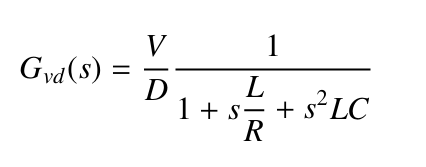  or as well as its, 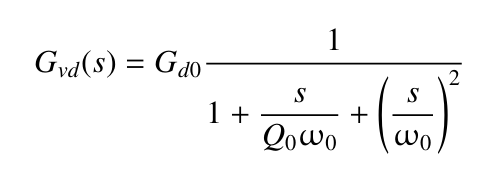

s = tf("s");

Q = R*sqrt(Cf/Lf);
omega = 1/(sqrt(Lf*Cf));
f0 = omega/(2*pi);

Gvd = Adc/(1+s/(Q*omega)+s^2/omega^2)

Gvd =
 
           3.2e11
  ------------------------
  4000 s^2 + 1e07 s + 4e10
 
Continuous-time transfer function.




Gvd = Adc*(R+(R*Cf*Rc)*s)/(R+Rl+(Lf+Rc*Cf*R+Rl*Cf*R+Rl*Rc*Cf)*s+(R+Rc)*Lf*Cf*s^2)

Gvd =
 
         3.2e-05 s + 1.6
  -----------------------------
  2.1e-08 s^2 + 5.4e-05 s + 0.2
 
Continuous-time transfer function.



Gvd2 = Adc*(2*R+(2*R*Cf*Rc)*s)/(2*R+Rl+(Lf+Rc*Cf*2*R+Rl*Cf*2*R+Rl*Rc*Cf)*s+(2*R+Rc)*Lf*Cf*s^2)

Gvd2 =
 
         6.4e-05 s + 3.2
  -----------------------------
  4.1e-08 s^2 + 5.8e-05 s + 0.4
 
Continuous-time transfer function.



The line-to-output transfer function (Gvg(s)) can be also extracted although we will not be using it.

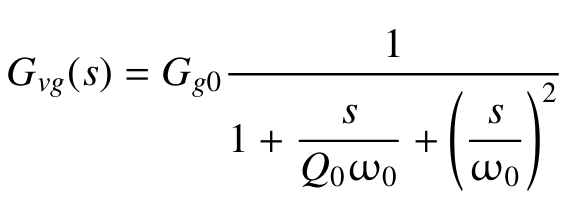

Gvg = N2/N1*(Vo/Vd)*1/(1+s/(Q*omega)+s^2/omega^2);

## A) Voltage Mode Controller Design

Aim is to design a voltage mode controller with gain crossover frequency of 10 kHz and a phase margin of 45 degrees.

The loop gain of the system is Ts;

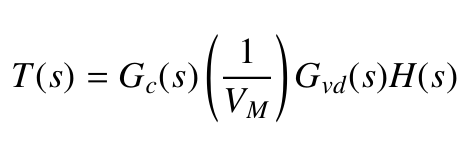

Defining uncompensated loop gain introduces the equation below, this has unity gain.

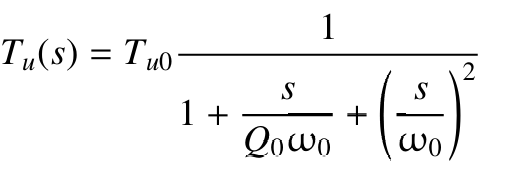

where the dc gain is

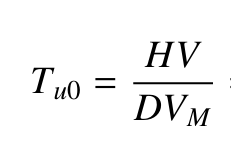

Tu0 = (Hs*Tms*Vd);
Tu = Tu0*(R+(R*Cf*Rc)*s)/(R+Rl+(Lf+Rc*Cf*R+Rl*Cf*R+Rl*Rc*Cf)*s+(R+Rc)*Lf*Cf*s^2);

Here we constructed Tu(s), later for the step load decrease we will need to increase the R (load resistance) to 400 $m\Omega$ and to 4$\Omega$ hence we will need to define new Tu(s) functions.

Tu2   $\longrightarrow$ 2R

Tu10 $\longrightarrow$ 10R

Tu2  = Tu0*(2*R+(2*R*Cf*Rc)*s)/(2*R+Rl+(Lf+Rc*Cf*2*R+Rl*Cf*2*R+Rl*Rc*Cf)*s+(2*R+Rc)*Lf*Cf*s^2);
Tu10 = Tu0*(R+(R*Cf*Rc)*s)/(R+Rl+(Lf+Rc*Cf*R+Rl*Cf*R+Rl*Rc*Cf)*s+(R+Rc)*Lf*Cf*s^2);

Also for the case of increasing the input voltage by 1 V, we need to define a separate Tu(s) function that has the input relation multiplied with 25/24.

Tu1 $\longrightarrow$ Vin from 24 to 25

Tu

Tu =
 
        4.08e-05 s + 2.04
  -----------------------------
  2.1e-08 s^2 + 5.4e-05 s + 0.2
 
Continuous-time transfer function.



systt = ss(Tu)

systt =
 
  A = 
          x1     x2
   x1  -2571  -2325
   x2   4096      0
 
  B = 
        u1
   x1  128
   x2    0
 
  C = 
          x1     x2
   y1  15.18  185.3
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Tu1 = ss(systt.A,systt.B.*(25/24),systt.C ,systt.D)

Tu1 =
 
  A = 
          x1     x2
   x1  -2571  -2325
   x2   4096      0
 
  B = 
          u1
   x1  133.3
   x2      0
 
  C = 
          x1     x2
   y1  15.18  185.3
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% Tu1 = tf(Tu1)

Tu1 =
 
     2024 s + 1.012e08
  -----------------------
  s^2 + 2571 s + 9.524e06
 
Continuous-time transfer function.



Continuing with the design. We need to check the bode plot of the uncompansated loop transfer function (Tu(s)).

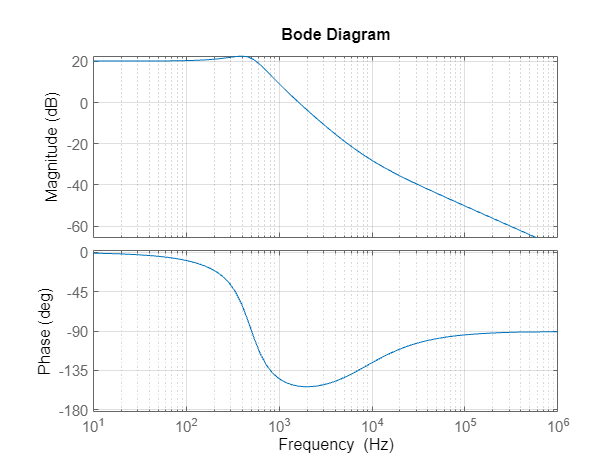

bode(Tu);
grid on


% select crossover freq of fc = 10 kHz, or 1/20 of Fsw
fc = 10e3;
% at 10 Khz gain margin is -30 dB so we need +30 dB to get unity gain
% also at 10 kHz we have phase margin of -175 degrees, lets design for
% phase margin of +45 degrees. Selecting lead compansator (PD)
theta = 45 

theta = 45

fz = fc*sqrt(1-sind(theta))/(sqrt(1+sind(theta)))

fz = 4.1421e+03

fp = fc*sqrt(1+sind(theta))/(sqrt(1-sind(theta)))

fp = 2.4142e+04

Know we gain the pole and zero locations of the controller with required phase margin at crossover frequency. 

Calculating the required controller gain is done with, 

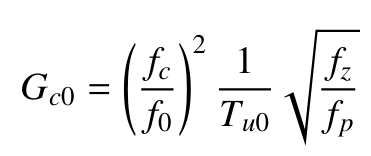

Gc0 = ((fc/f0)^2)*sqrt((fz)/(fp))/Tu0

Gc0 = 16.0319

Then the controller transfer function results in,

Gc = Gc0*(1+s/(2*pi*fz))/((1+s/(2*pi*fp)))

Gc =
 
  2.432e06 s + 6.329e10
  ---------------------
  2.603e04 s + 3.948e09
 
Continuous-time transfer function.



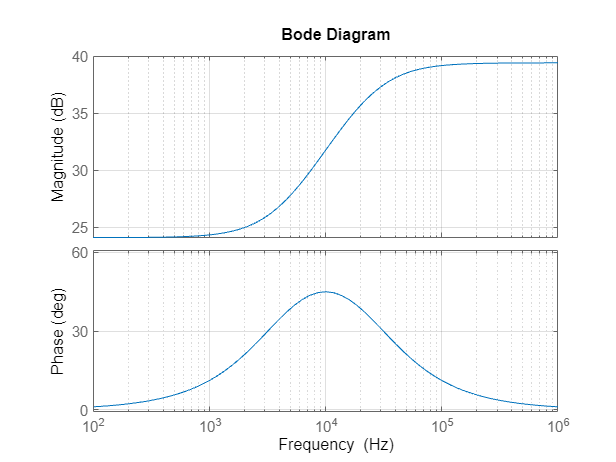

bode(Gc)
grid on

Here we have the phase margin of 45 degrees at 10 kHz and gain at crossover frequency is measured to be 32 dB. This falls in our design criteria and we can continue along.

The loop transfer function is the multiplication of uncompansated circuitry and the controller. For different simulations requiring alteration of the load or the input voltage we have different transfer functions, however the controller's  transfer function is same in all below (Gc(s)).

Ts10 $\longrightarrow$ Uncompensated Tf with R = 10R

Ts2  $\longrightarrow$ Uncompensated Tf with R = 2R

Ts1  $\longrightarrow$  Uncompensated Tf with input varied from 24V to 25V (1V step)

Ts = Tu*Gc;
Ts10 = Tu10*Gc;
Ts1 = Tu1*Gc;
Ts2 = Tu2*Gc;

Checking the open-loop bode diagram verifies the gain margin which shows unity gain at 10 kHz and phase margin of 45 degrees at crossover frequency. This ensures that the design is correct.

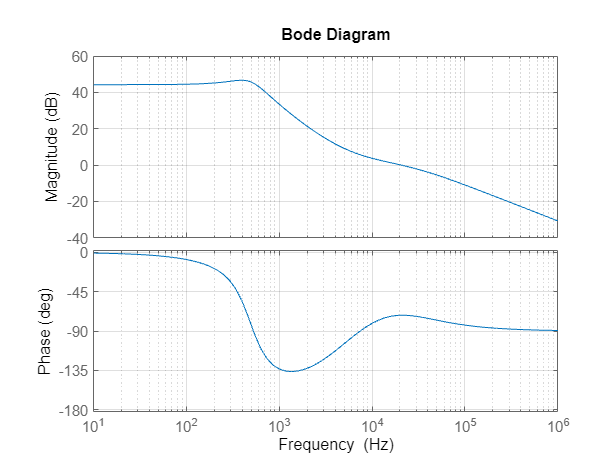

bode(Ts)
grid on

A simple step response test results in that for a change in reference from 0 to 4 V results in a fast and damped fit of the output voltage to the required 4V level.

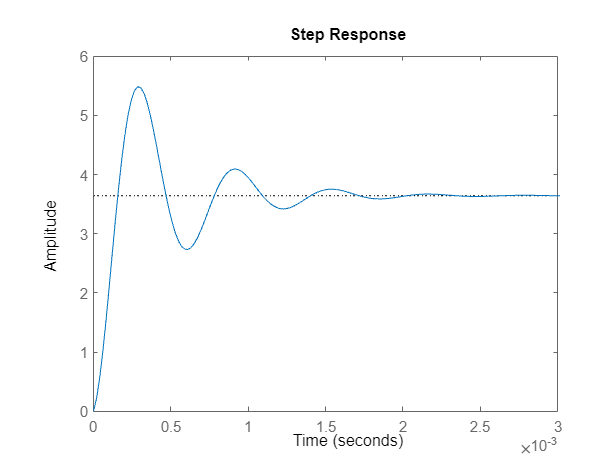

step(4*Tu/(1+Tu))

Close loop transfer function is calculated as,


$$G_{\textrm{cl}} \left(s\right)=\frac{V_{\textrm{ref}} \cdot T\left(s\right)}{1+T\left(s\right)}$$


Gcl = 4*Ts/(1+Ts);
Gcl1 = 4*Ts1/(1+Ts1);
Gcl10 = 4*Ts10/(1+Ts10);
Gcl2 = 4*Ts2/(1+Ts2);
Gcl = Gvd;
Gcl2 = Gvd2;

Again we have different close loop systems to simulate load change and input change conditions, the controller block is identical in all of them.

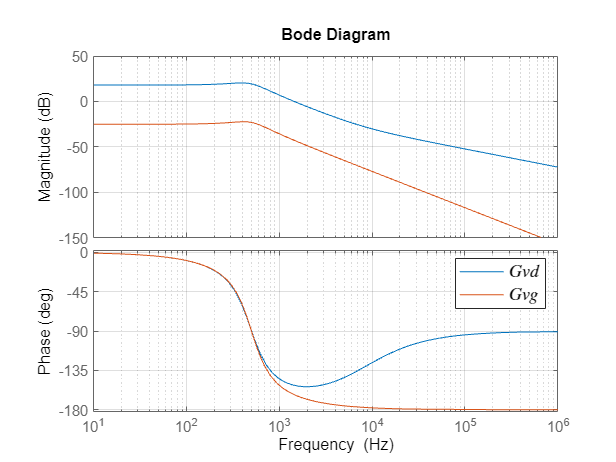

bode(Gvd)
hold on
bode(Gvg)
leg1 = legend('$G{vd}$','$G{vg}$');
set(leg1,'Interpreter','latex');
set(leg1,'FontSize',12);
grid on;
hold off

### **B) The Step Load Change (from 100% to 50%)**

sys1 = ss(Gcl);
sys2 = ss(Gcl2);

% Time vector for each system
t1 = 0:0.000001:0.00999999;  % Simulation time for system 1
t2 = 0.01:0.000001: 0.1999999;  % Simulation time for system 2

% Input for each system
u1 = ones(size(t1))*0.5;  % Input for system 1
u2 = ones(size(t2))*0.5;  % Input for system 2

% Simulate the first system
[y1, t1_out, x1] = lsim(sys1, u1, t1);
sys1

sys1 =
 
  A = 
          x1     x2
   x1  -2571  -2325
   x2   4096      0
 
  B = 
        u1
   x1  128
   x2    0
 
  C = 
          x1     x2
   y1   11.9  145.3
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




% Extract the final state of the first system
x1_final = x1(end, :);  % Final states of system 1
% Simulate the second system with initial conditions
[y2, t2_out, x2] = lsim(sys2, u2, t2, x1_final)

y2 =     4.0976
    4.0976
    4.0975
    4.0975
    4.0975
    4.0975
    4.0974
    4.0974
    4.0974
    4.0974


t2_out =     0.0100
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100


x2 =     0.0000    0.0275
   -0.0000    0.0275
   -0.0000    0.0275
   -0.0000    0.0275
   -0.0000    0.0275
   -0.0000    0.0275
   -0.0000    0.0275
   -0.0000    0.0275
   -0.0000    0.0275
   -0.0000    0.0275


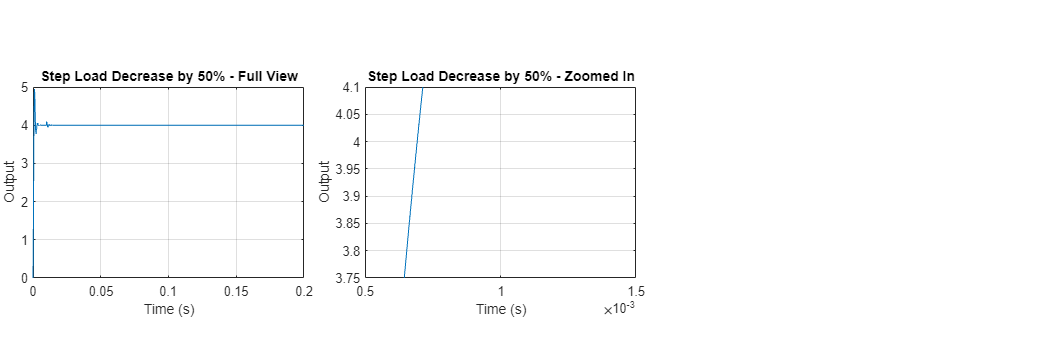

% Combine the results
t_combined = [t1_out; t2_out];
y_combined = [y1; y2];

figure;

set(gcf, 'Position', [100, 100, 1200, 400]); % [x, y, width, height]

subplot(1, 2, 1);
plot(t_combined, y_combined);
xlabel('Time (s)');
ylabel('Output');
title('Step Load Decrease by 50% - Full View');
grid on;
set(gca, 'Position', [0.032, 0.2, 0.26, 0.55]); 

subplot(1, 2, 2);
plot(t_combined, y_combined);
xlabel('Time (s)');
ylabel('Output');
title('Step Load Decrease by 50% - Zoomed In');
grid on;
ylim([3.75 4.1]);
xlim([0.0005 0.0015]);
set(gca, 'Position', [0.35, 0.2, 0.26, 0.55]); 

**C) The Dynamic Load Response (from 10% to 100% and back to 10%)**

sys1 = ss(Gcl);
sys2 = ss(Gcl2);

% Time vector for each system
t1 = 0:0.000001:0.000999999;  % Simulation time for system 1
t2 = 0.001:0.000001:0.001999999;  % Simulation time for system 2
t3 = 0.002:0.000001:0.002999999;  % Simulation time for system 3

% Input for each system
u1 = ones(size(t1));  % Input for system 1
u2 = ones(size(t2));  % Input for system 2
u3 = ones(size(t2));

% Simulate the first system
[y1, t1_out, x1] = lsim(sys1, u1, t1);

% Extract the final state of the first system
x1_final = x1(end, :);  % Final states of system 1
% Simulate the second system with initial conditions
[y2, t2_out, x2] = lsim(sys2, u2, t2, x1_final);

% Extract the final state of the first system
x2_final = x2(end, :);  % Final states of system 1
% Simulate the second system with initial conditions
[y3, t3_out, x3] = lsim(sys1, u3, t3, x2_final);

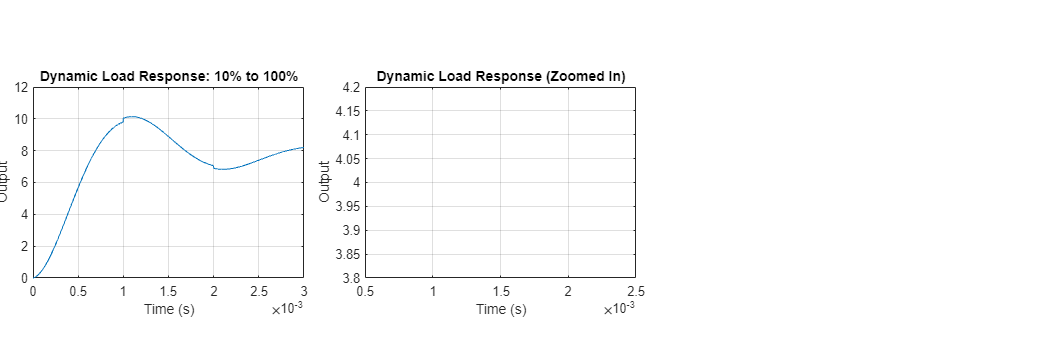

% Combine the results
t_combined = [t1_out; t2_out; t3_out];
y_combined = [y1; y2; y3];

figure;

% Resize the figure
set(gcf, 'Position', [100, 100, 1200, 400]);

subplot(1, 2, 1);
plot(t_combined, y_combined);
xlabel('Time (s)');
ylabel('Output');
title('Dynamic Load Response: 10% to 100%');
grid on;
set(gca, 'Position', [0.032, 0.2, 0.26, 0.55]); 

subplot(1, 2, 2);
plot(t_combined, y_combined);
xlabel('Time (s)');
ylabel('Output');
title('Dynamic Load Response (Zoomed In)');
grid on;
ylim([3.8 4.2]); % Zoom in on output voltage range
xlim([0.0005 0.0025]); % Zoom in on specific time range
set(gca, 'Position', [0.35, 0.2, 0.26, 0.55]); 

### **D) The Step Input Voltage Change (from 24 V to 25 V)**

sys1 = systt

sys1 =
 
  A = 
          x1     x2
   x1  -2571  -2325
   x2   4096      0
 
  B = 
        u1
   x1  128
   x2    0
 
  C = 
          x1     x2
   y1  15.18  185.3
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys2 = Tu1

sys2 =
 
  A = 
          x1     x2
   x1  -2571  -2325
   x2   4096      0
 
  B = 
          u1
   x1  133.3
   x2      0
 
  C = 
          x1     x2
   y1  15.18  185.3
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




% Time vector for each system
t1 = 0:0.000001:0.00999999;  % Simulation time for system 1
t2 = 0.01:0.000001:0.01999999;  % Simulation time for system 2

% Input for each system
u1 = ones(size(t1))*0.5;  % Input for system 1
u2 = ones(size(t2))*0.5;  % Input for system 2

% Simulate the first system
[y1, t1_out, x1] = lsim(sys1, u1, t1);

% Extract the final state of the first system
x1_final = x1(end, :);  % Final states of system 1
% Simulate the second system with initial conditions
[y2, t2_out, x2] = lsim(sys2, u2, t2, x1_final);

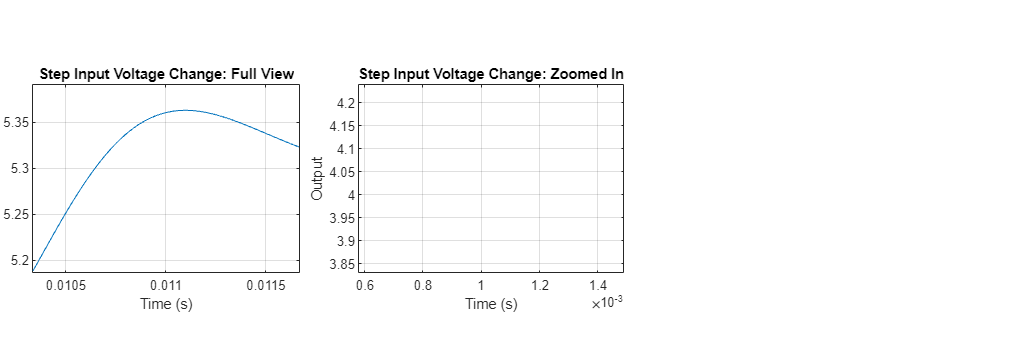

% Combine the results
t_combined = [t1_out; t2_out];
y_combined = [y1; y2];

figure;

set(gcf, 'Position', [100, 100, 1200, 400]); % [x, y, width, height]

subplot(1, 2, 1);
plot(t_combined, y_combined);
xlabel('Time (s)');
ylabel('Output');
title('Step Input Voltage Change: Full View');
grid on;
set(gca, 'Position',[0.032, 0.2, 0.26, 0.55]); 

subplot(1, 2, 2);
plot(t_combined, y_combined);
xlabel('Time (s)');
ylabel('Output');
title('Step Input Voltage Change: Zoomed In');
grid on;
ylim([3.8 4.25]); % Focus on the specific output range
xlim([0.0005 0.0015]); % Focus on the specific time range
set(gca, 'Position', [0.35, 0.2, 0.26, 0.55]);